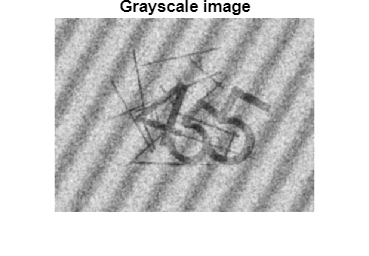

    I = imread("Train\captcha_0100.png");
    I_gray = rgb2gray(I);
    imshow(I_gray)
    title("Grayscale image")

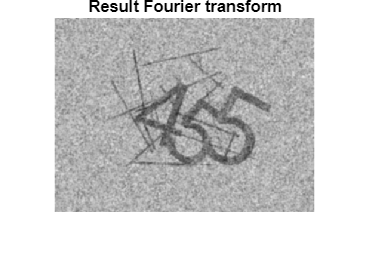

    
    %Fourier transform
    fft = fft2(double(I_gray));
    fftshifted = fftshift(fft);
    
    magnitude = log(abs(fftshifted) + 1);
    % imshow(magnitude, []);
    % title("Magnitude")
    
    size_image = size(magnitude);
    
    tan_min = tan(deg2rad(66));
    tan_max = tan(deg2rad(67));
    
    for i = 1:size_image(1)
        for j = 1:size_image(2)
            tangent = (j - round(0.5 * size_image(2)))/(i - round(0.5 * size_image(1)));     
            if tangent > tan_min  && tangent < tan_max
                fftshifted(i,j) = 0;
            end 
        end 
    end 
    
    magnitude = log(abs(fftshifted) + 1);
    % imshow(magnitude, []);
    % title("Result Magnitude")
    
    ifftshifted = ifftshift(fftshifted);
    res = uint8(ifft2(ifftshifted));
    imshow(res);
    title("Result Fourier transform");

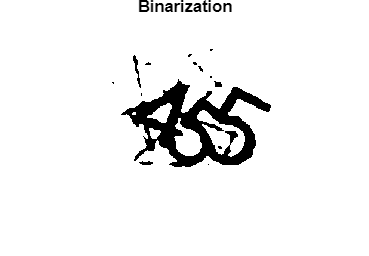


    res = imgaussfilt(res,3);

    %Binarization
    I_binary = imbinarize(res);
    imshow(I_binary);
    title("Binarization")

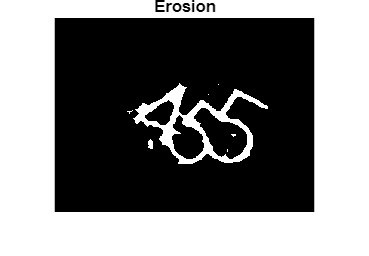

    I_binary = ~I_binary;
    
    
    %Erosion
    se = strel("diamond",4);
    I_eroded = imerode(I_binary,se);
    imshow(I_eroded);
    title("Erosion")

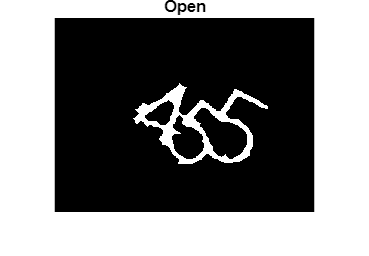


    I_open = bwareaopen(I_eroded, 300);
    imshow(I_open);
    title("Open")

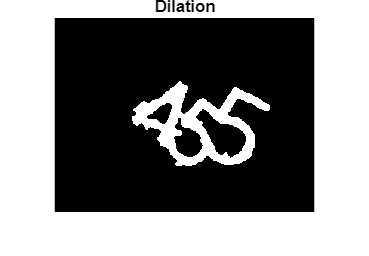


    %Dilation
    se = strel("disk",4);
    I_dilated = imdilate(I_open,se);
    imshow(I_dilated);
    title("Dilation")

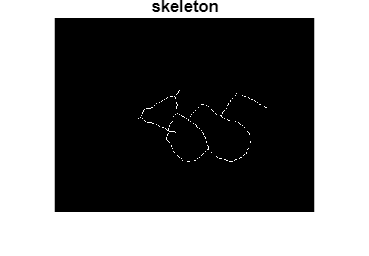

    I_skeleton = bwskel(I_dilated,'MinBranchLength',3);
    imshow(I_skeleton);
    title("skeleton")

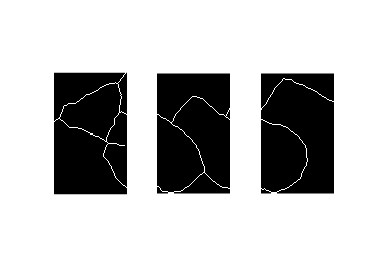


    count = bwconncomp(I_skeleton,8);
    props = regionprops(count, 'Image');

    if count.NumObjects == 1
        [h,w] = size(props(1).Image);
        split = round(w/3);
        d1 = imcrop(props(1).Image,[0 0 split h]);
        d2 = imcrop(props(1).Image,[split 0 split h]);
        d3 = imcrop(props(1).Image,[split*2 0 split h]);
        
        figure;
        subplot(1,3,1);
        imshow(d1);
        subplot(1,3,2);
        imshow(d2);
        subplot(1,3,3);
        imshow(d3);
       
    elseif count.NumObjects == 2
        [h1,w1] = size(props(1).Image);
        [h2,w2] = size(props(2).Image);
        if w1 > w2 % Split first image
            d1 = imcrop(props(1).Image,[0 0 round(w1/2) h1]);
            d2 = imcrop(props(1).Image,[round(w1/2) 0 round(w1/2) h1]);
            d3 = props(2).Image;
        else % Split second image
            d1 = props(1).Image;
            d2 = imcrop(props(2).Image,[0 0 round(w2/2) h2]);
            d3 = imcrop(props(2).Image,[round(w2/2) 0 round(w2/2) h2]);
        end
        
        figure;
        subplot(1,3,1);
        imshow(d1);
        subplot(1,3,2);
        imshow(d2);
        subplot(1,3,3);
        imshow(d3);

    elseif count.NumObjects == 3
        
        figure;
        subplot(1,3,1);
        imshow(props(1).Image);
        subplot(1,3,2);
        imshow(props(2).Image);
        subplot(1,3,3);
        imshow(props(3).Image);
   elseif count.NumObjects == 4 %some captchas detect 4 digits. can be skipped
        figure;
        subplot(1,4,1);
        imshow(props(1).Image);
        subplot(1,4,2);
        imshow(props(2).Image);
        subplot(1,4,3);
        imshow(props(3).Image);
        subplot(1,4,4);
        imshow(props(4).Image);
        
    end